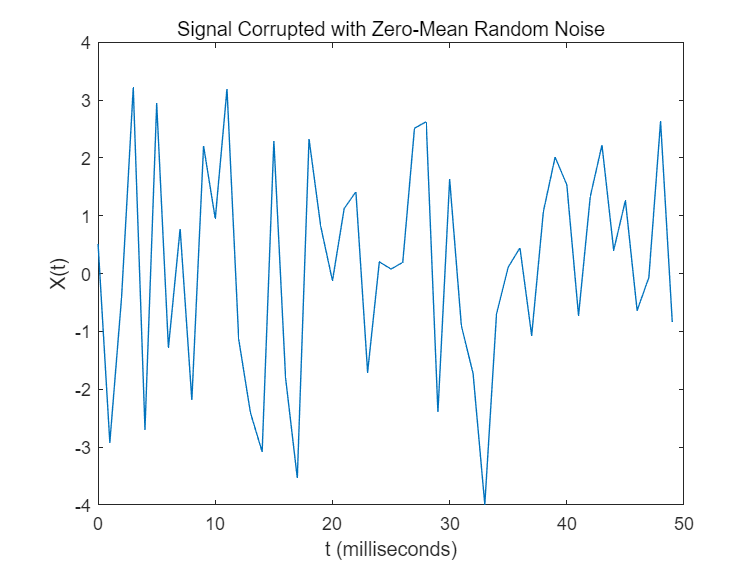

Fs = 1000;            % Sampling frequency                    
T = 1/Fs;             % Sampling period       
L = 1500;             % Length of signal
t = (0:L-1)*T;        % Time vector
S = 0.7*sin(2*pi*50*t) + sin(2*pi*120*t);
X = S + 2*randn(size(t));
plot(1000*t(1:50),X(1:50))
title('Signal Corrupted with Zero-Mean Random Noise')
xlabel('t (milliseconds)')
ylabel('X(t)')

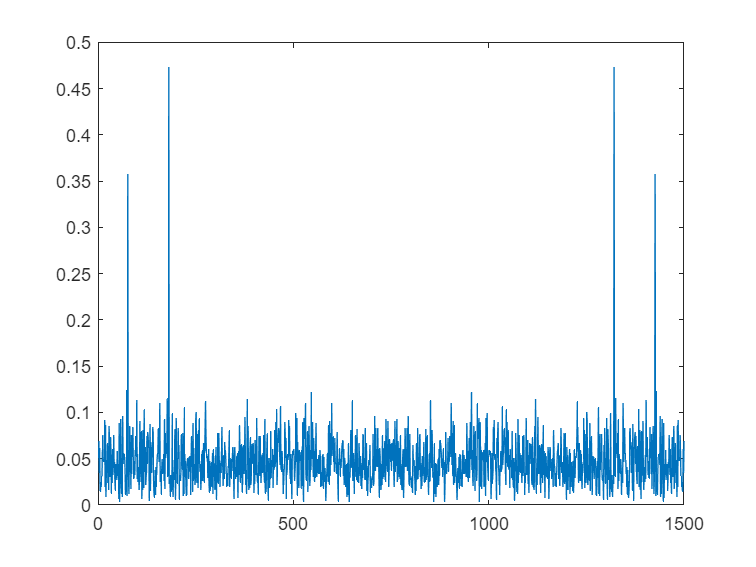

Y = fft(X);
P2 = abs(Y/L);
plot(1:length(P2), P2)

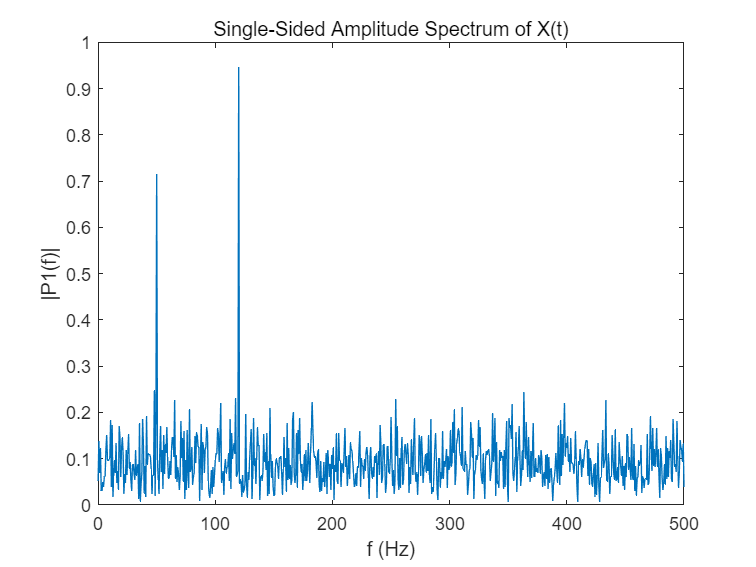

P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;
plot(f,P1) 
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)')
ylabel('|P1(f)|')

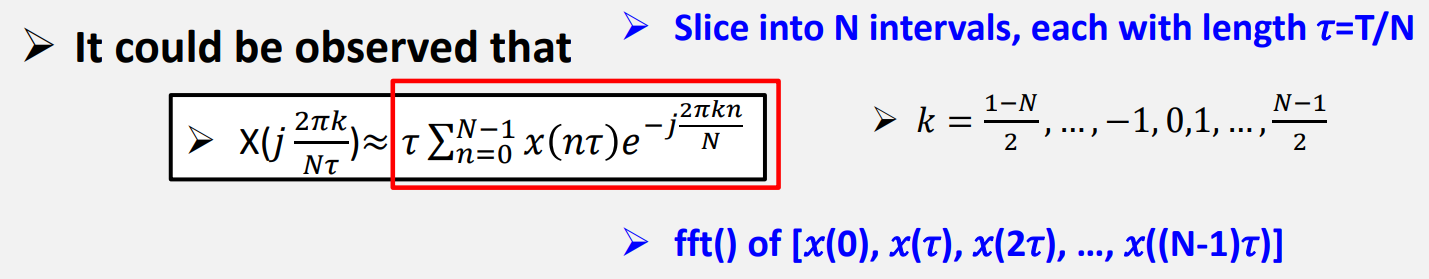

Y = fft(S);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);

plot(f,P1) 
title('Single-Sided Amplitude Spectrum of S(t)')
xlabel('f (Hz)')
ylabel('|P1(f)|')
clear; close; clc;

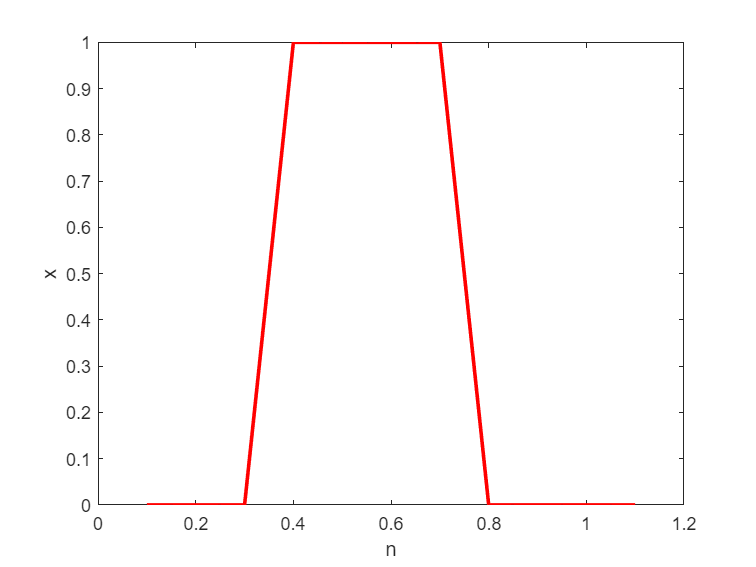

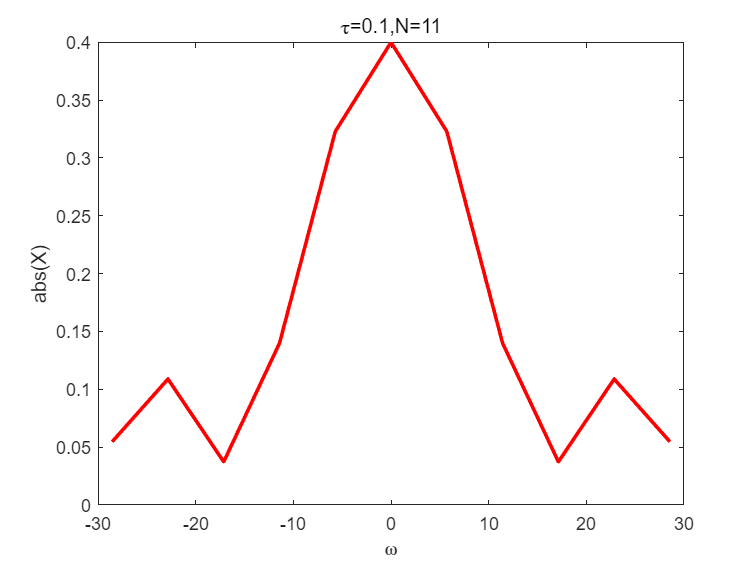

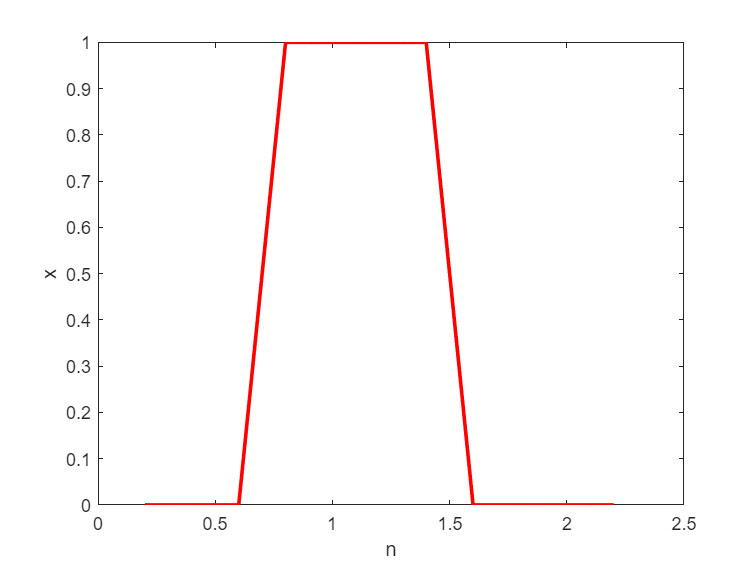

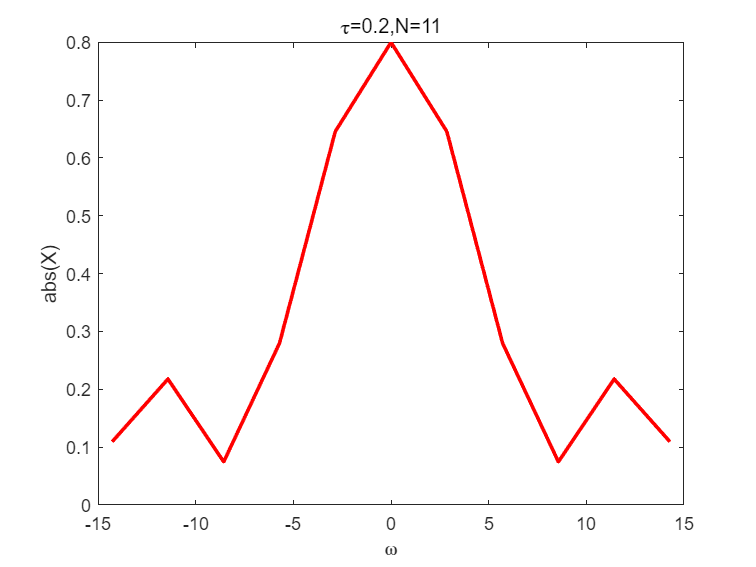

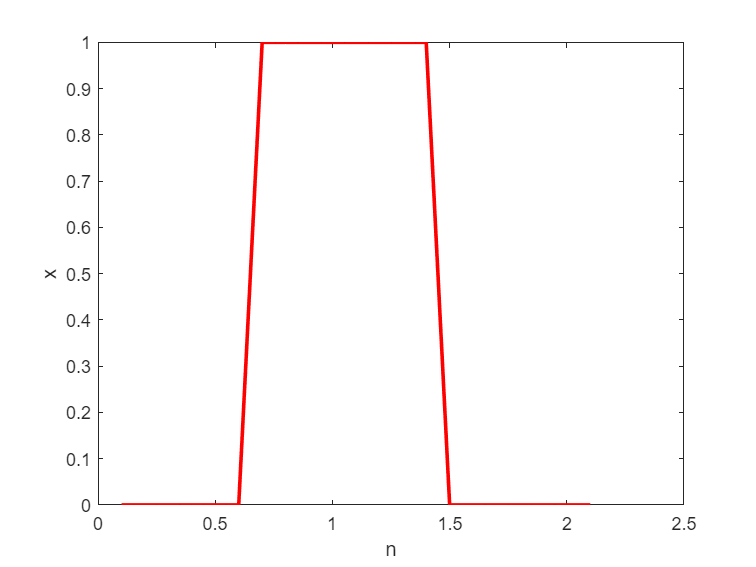

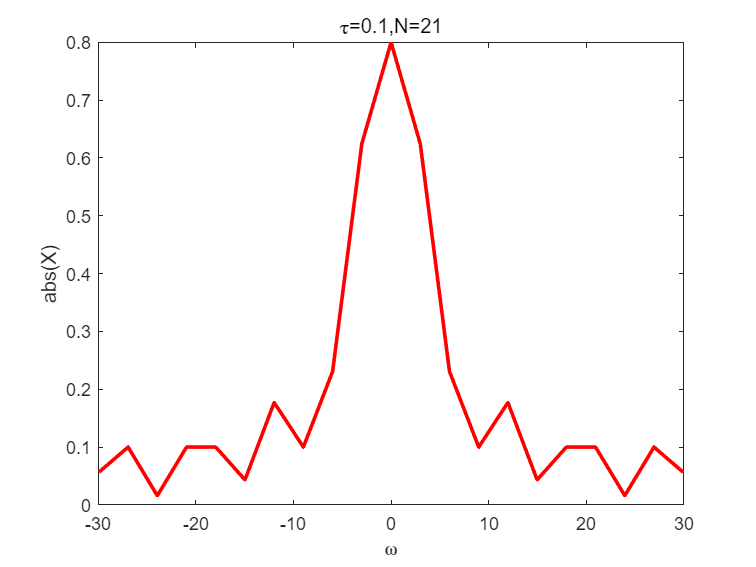

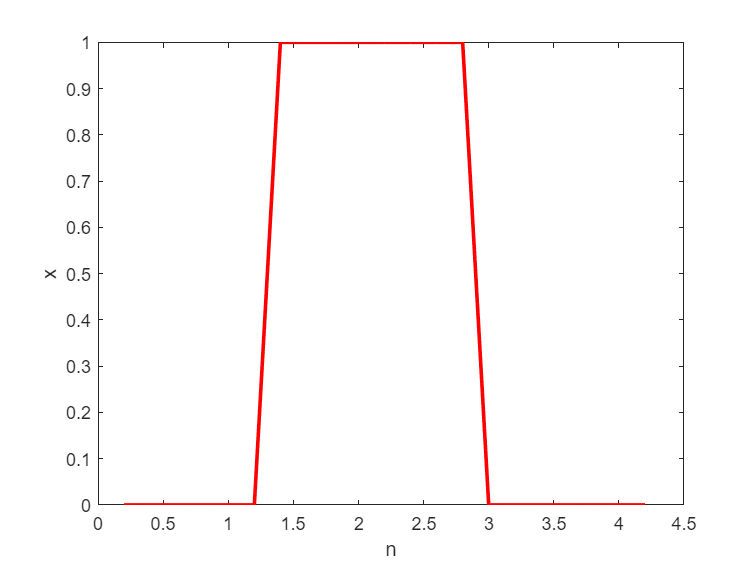

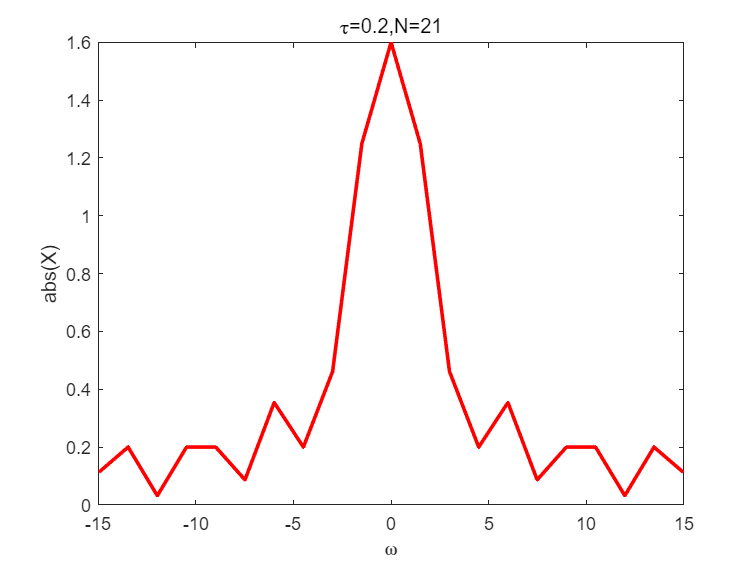

clear; close; clc;


% legend(['\tau=' + tau , 'N=' + N])

taus=[0.1 0.2];
Ns=[11 21 151]; % N should be odd number
fno = 1;
for i = 1:3
    for j = 1:2
    N = Ns(i);
    tau = taus(j);
    T = N * tau;
    x=zeros(1,N);
    x(N/3:N*2/3) = x(N/3:N*2/3)+1; 
    figure(fno);
    fno = fno+1;
    plot([1:N]*tau,x,'r-','LineWidth',2)
    xlabel('n');ylabel('x');
    y=fftshift(fft(x));
    X=tau*y;
    lb = (1-N)*pi/N/tau;
    ub = (N-1)*pi/N/tau;
    step = 2*pi/N/tau;
    figure(2)
    figure(fno);
    fno = fno+1;
    plot(lb:step:ub, abs(X),'r-','LineWidth',2);
    xlabel('\omega');ylabel('abs(X)');
    title("\tau="+tau+",N="+N)
    end
end

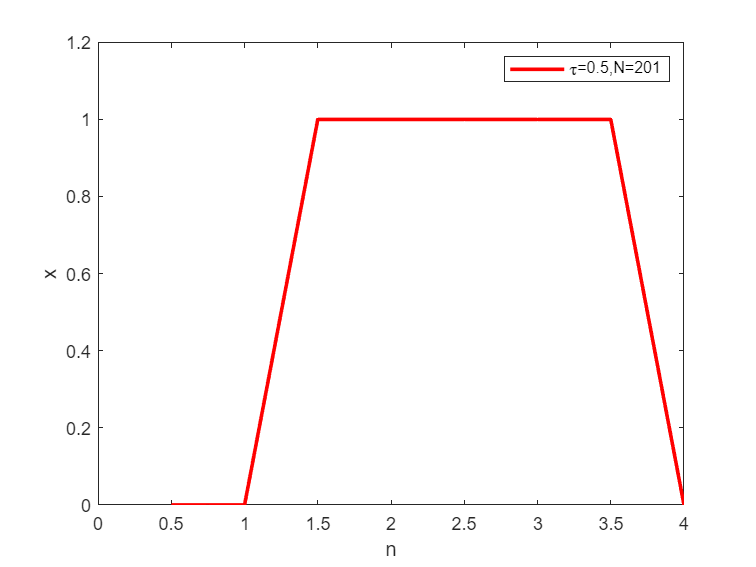

tau=0.5;
N=201; % N should be odd number,
T=N*tau;
x=[zeros(1,1/tau),ones(1,2/tau+1),zeros(1,N-3/tau-1)];
figure(1)
plot([1:N]*tau,x,'r-','LineWidth',2)
xlabel('n');ylabel('x');
axis([0 4 0 1.2])
legend('\tau=0.5,N=201')

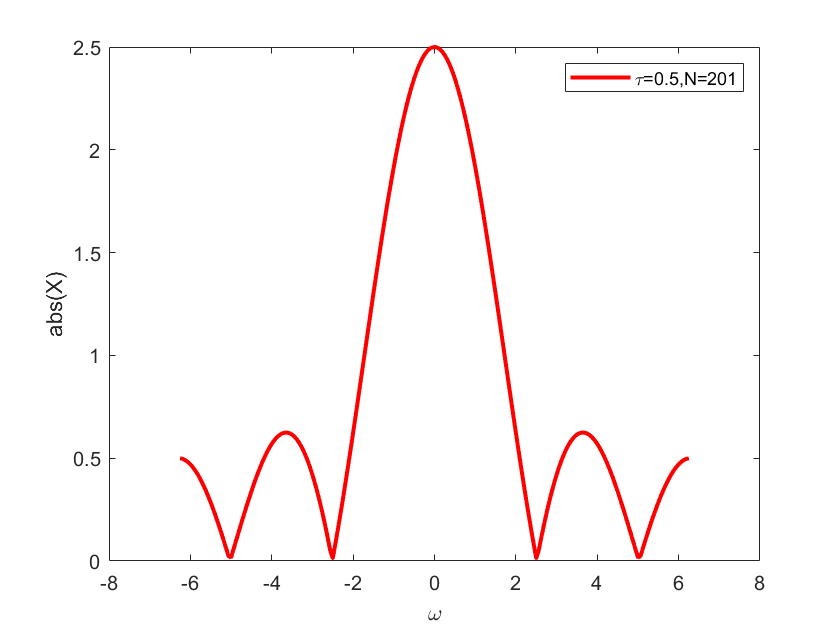

y=fftshift(fft(x));
X=tau*y;
lb = (1-N)*pi/N/tau;
ub = (N-1)*pi/N/tau;
step = 2*pi/N/tau;
figure(2)
plot(lb:step:ub, abs(X),'r-','LineWidth',2);
xlabel('\omega');ylabel('abs(X)');
legend('\tau=0.5,N=201')